# Tarea Semanal 4

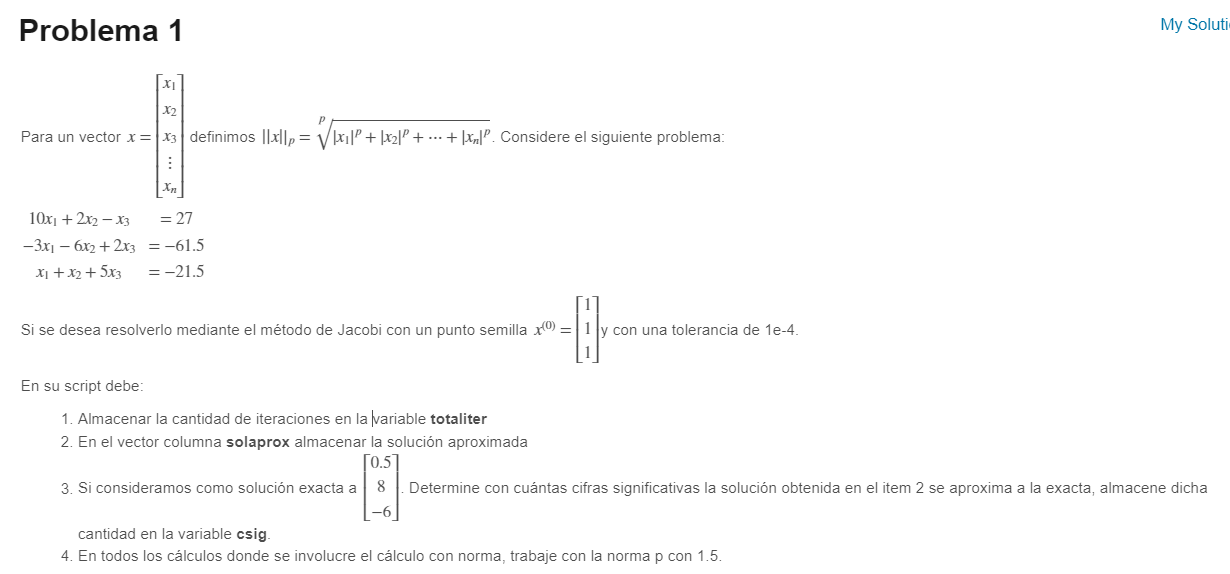

A = [10 2 -1; -3 -6 2; 1 1 5];
b = [27; -61.5; -21.5];
x0 = [1 1 1]';
Tol = 1e-4;

J = jacobi(A, b, x0, Tol);
[totaliter, ~] = size(J);
totaliter = totaliter - 1

totaliter = 9

solaprox = J(end, 1:3)'

solaprox =     0.5000
    7.9999
   -5.9999


function z = jacobi(A,b,x0,Tol)
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);

    Tj = inv(D)*(L+U);
    cj = inv(D)*b;

    error = 1;
    %it = 0;

    z = [x0' error];

    while error>Tol
        x1 = Tj*x0 + cj; % Iteración
        error = norm(x1-x0, inf)/norm(x1, inf); % Error
        z = [z; x1' error];
        x0 = x1;
    end
end